How to use this code: Just run it!

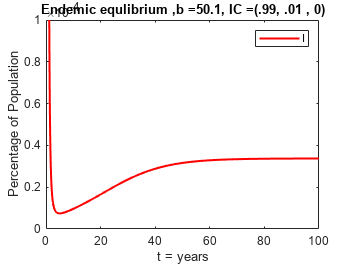

%This chink of code generates the figures 4,5 in the thesis
% calls function to generate endemic equilbirum plot
caller7

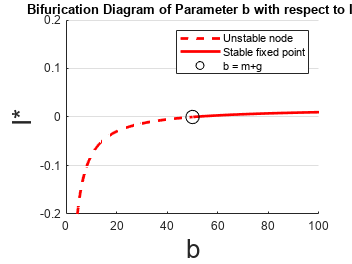

%start of code that nui;ds bifruication diagra, Fig 5
syms b
figure
%set parameters to 
m    = .015;
g    = 50;
w    = 1;
hold on
%plot unstable fixed points
fplot(((m+w)*(b-g-m))/(b*(g+m+w)),[0 m+g],"LineWidth",2,"Color","r","LineStyle","--")
%plot stale fixed points
hold on
fplot(((m+w)*(b-g-m))/(b*(g+m+w)),[50.3 1000],"LineWidth",2,"Color","r","LineStyle","-")
ylim([-.2 .2])
xlim([0 100])
set(gca,'XGrid','off','YGrid','on')
hold on
%plot bifurication point 
scatter(m+g,0,100,"black")
hold on 
xlabel("b","FontSize",20)
ylabel("I*","FontSize",20)
legend("Unstable node","Stable fixed point","b = m+g")
title("Bifurication Diagram of Parameter b with respect to I*")

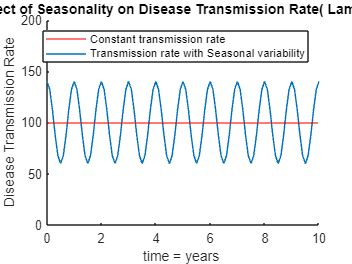

%This code plots the impact od seaosnality on transmission rate: Fig 8
t = [0:.1: 25];
b = 100;
%degree of seasonality 
b1 = .4;
y = 100;
lambda = b*(1 + b1*cos(2*pi*t));
figure
yline(y,"r")
hold on
plot (t,lambda)
ylim([0 200])
xlim([0 10])
ylabel("Disease Transmission Rate")
xlabel("time = years ")
legend("Constant transmission rate","Transmission rate with Seasonal variability")
title("Effect of Seasonality on Disease Transmission Rate( Lambda) ")

%This chunk of code estimates the Lyapunov exponent of the system as b1 is
%perturbed(Fig 13
%fix the rest of the parameters
   m    = .015;
   b   = 100;
   g    = 50;
   w    = 1;
  %define system of OdE's
odefun = @(t,x,b1) [m - m*x(1) - b*(1 + b1*cos(pi*2*t))*x(1)*x(2) + w*x(3); 
               b*(1 + b1*cos(pi*2*t))*x(1)*x(2) - m*x(2) - g*x(2); 
              g*x(2) - m*x(3) - w*x(3)];

% Choose a range of values for the parameter b
b_vals = linspace(0,1,30);

% Choose an initial condition
x0 = [0.5; 0.02; 0.48];

% Compute the Lyapunov exponent for each value of b
lambda_vals = zeros(size(b_vals));
for i = 1:length(b_vals)
    % Integrate the ODEs
    [t,x] = ode45(@(t,x) odefun(t,x,b_vals(i)), [0 30], x0);

    lambda_vals(i) = lyapunovExponent( [t,x(:,2)]);
end

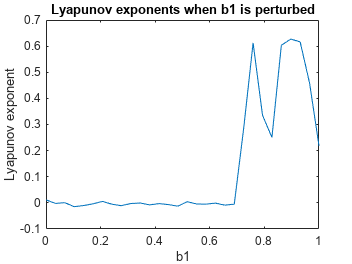



% Plot the Lyapunov exponent as a function of b1
figure
plot(b_vals, lambda_vals);
xlabel('b1');
ylabel('Lyapunov exponent');
title('Lyapunov exponents when b1 is perturbed')

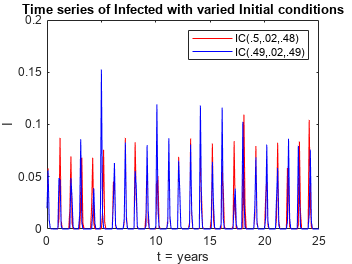


% this chunck of code  generates the the tiemseries and graphs for chaotic
% behavior at the initial condition (.5,.02,.48) whentthe system is chaotic
% Fig 13
%define parameter values 
m    = .015;
   b = 100;
   g    = 50;
   w    = 1;
  %define system of ODE's
odefun = @(t,x,b1) [m - m*x(1) - b*(1 + b1*cos(pi*2*t))*x(1)*x(2) + w*x(3); 
               b*(1 + b1*cos(pi*2*t))*x(1)*x(2) - m*x(2) - g*x(2); 
              g*x(2) - m*x(3) - w*x(3)];

b_vals = .65 ;%linspace(0, 1000, 50);

%IC 1
x0 = [0.5; 0.02;0.48];
%IC 2
x0_2 = [0.49; 0.02;0.49];
%x0_2 = [0.5; 0.11;0.39];

%Evaluate timeseries for Infected 
    [t1,x] = ode45(@(t,x) odefun(t,x,b_vals), [0:0.1:25], x0);
    I1 = x(:,2);
    
    [t2,x] = ode45(@(t,x) odefun(t,x,b_vals), [0:0.1:25], x0_2);
     I2 = x(:,2);
     %plot timeseries of I at IC1 and IC2
     figure
     plot(t1,I1,'red',t2,I2,'blue')
     ylim([0 .2])
 
     title("Time series of Infected with varied Initial conditions")
     xlabel("t = years")
     ylabel("I")
     legend(["IC(.5,.02,.48)","IC(.49,.02,.49)"])

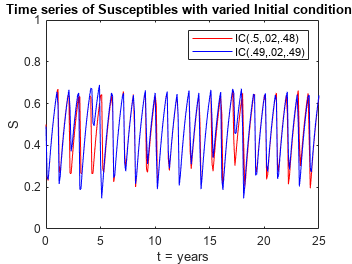

%Evaluate timeseries for Susceptable  
    [t3,x] = ode45(@(t,x) odefun(t,x,b_vals), [0:0.1:25], x0);
    S1 = x(:,1);
    
    [t4,x] = ode45(@(t,x) odefun(t,x,b_vals), [0:0.1:25], x0_2);
     S2 = x(:,1);
      %plot timeseries of S at IC1 and IC2
     figure
     plot(t3,S1,'red',t4,S2,'blue')
     ylim([0 1])
     xlim([0 25])
     title("Time series of Susceptibles with varied Initial conditions")
     xlabel("t = years")
     ylabel("S")
     legend(["IC(.5,.02,.48)","IC(.49,.02,.49)"])

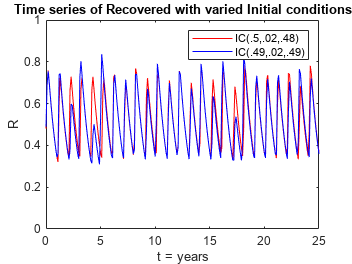

%Evaluate timeseries for Recovered
    [t5,x] = ode45(@(t,x) odefun(t,x,b_vals), [0:0.1:25], x0);
    R1 = x(:,3);
    
    [t4,x] = ode45(@(t,x) odefun(t,x,b_vals), [0:0.1:25], x0_2);
     R2 = x(:,3);
      %plot timeseries of R at IC1 and IC2
     figure
     plot(t4,R1,'red',t5,R2,'blue')
     ylim([0 1])
     xlim([0 25])
     title("Time series of Recovered with varied Initial conditions")
     xlabel("t = years")
     ylabel("R")
       legend(["IC(.5,.02,.48)","IC(.49,.02,.49)"])

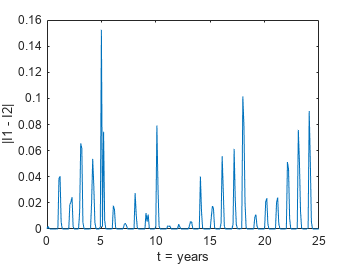

  %plot difference for I  
     
     figure
     plot(t1,abs(I1-I2))
     ylabel("|I1 - I2|")
     xlabel("t = years")

     norm(I1-I2)

ans = 0.3312

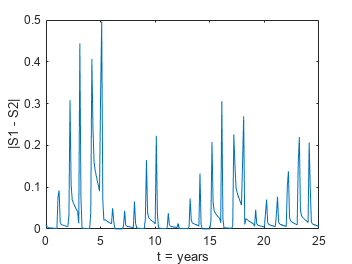

  %plot difference for S  
     figure
     plot(t1,abs(S1-S2))
     ylabel("|S1 - S2|")
     xlabel("t = years")

     
     norm(S1-S2)

ans = 1.2974

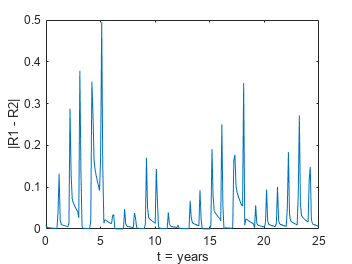

     %plot difference for R  
     figure
     plot(t1,abs(R1-R2))
      ylabel("|R1 - R2|")
     xlabel("t = years")

     norm(R1-R2)

ans = 1.2282

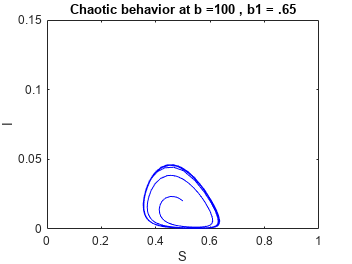

%caller functiosn for Fig 11a and 11b which shows 2d chaos when b1=.65 and
%periodic behavior when b =.1
caller2

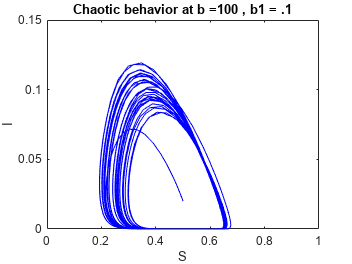

caller3

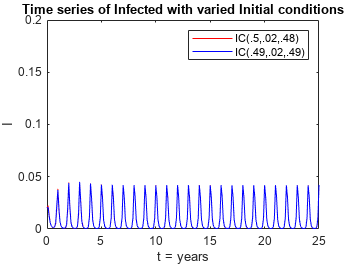

% this chunck of code  generates the the tiemseries and graphs for chaotic
% behavior at the initial condition (.5,.02,.48) when the system is
% predictable
% Fig 11
%define parameter values 
m    = .015;
   b = 100;
   g    = 50;
   w    = 1;
  %define system of ODE's
odefun = @(t,x,b1) [m - m*x(1) - b*(1 + b1*cos(pi*2*t))*x(1)*x(2) + w*x(3); 
               b*(1 + b1*cos(pi*2*t))*x(1)*x(2) - m*x(2) - g*x(2); 
              g*x(2) - m*x(3) - w*x(3)];

b_vals = .1 ;%linspace(0, 1000, 50);

%IC 1
x0 = [0.5; 0.02;0.48];
%IC 2
x0_2 = [0.49; 0.02;0.49];
%x0_2 = [0.5; 0.11;0.39];

%Evaluate timeseries for Infected 
    [t1,x] = ode45(@(t,x) odefun(t,x,b_vals), [0:0.1:25], x0);
    I1 = x(:,2);
    
    [t2,x] = ode45(@(t,x) odefun(t,x,b_vals), [0:0.1:25], x0_2);
     I2 = x(:,2);
     %plot timeseries of I at IC1 and IC2
     figure
     plot(t1,I1,'red',t2,I2,'blue')
     ylim([0 .2])
 
     title("Time series of Infected with varied Initial conditions")
     xlabel("t = years")
     ylabel("I")
     legend(["IC(.5,.02,.48)","IC(.49,.02,.49)"])

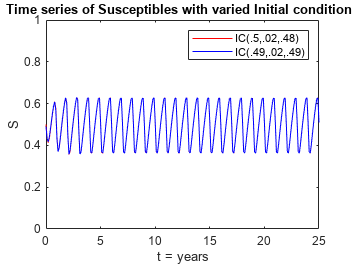

%Evaluate timeseries for Susceptable  
    [t3,x] = ode45(@(t,x) odefun(t,x,b_vals), [0:0.1:25], x0);
    S1 = x(:,1);
    
    [t4,x] = ode45(@(t,x) odefun(t,x,b_vals), [0:0.1:25], x0_2);
     S2 = x(:,1);
      %plot timeseries of S at IC1 and IC2
     figure
     plot(t3,S1,'red',t4,S2,'blue')
     ylim([0 1])
     xlim([0 25])
     title("Time series of Susceptibles with varied Initial conditions")
     xlabel("t = years")
     ylabel("S")
     legend(["IC(.5,.02,.48)","IC(.49,.02,.49)"])

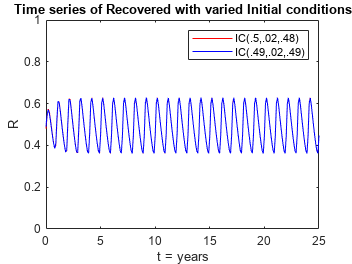

%Evaluate timeseries for Recovered
    [t5,x] = ode45(@(t,x) odefun(t,x,b_vals), [0:0.1:25], x0);
    R1 = x(:,3);
    
    [t4,x] = ode45(@(t,x) odefun(t,x,b_vals), [0:0.1:25], x0_2);
     R2 = x(:,3);
      %plot timeseries of R at IC1 and IC2
     figure
     plot(t4,R1,'red',t5,R2,'blue')
     ylim([0 1])
     xlim([0 25])
     title("Time series of Recovered with varied Initial conditions")
     xlabel("t = years")
     ylabel("R")
       legend(["IC(.5,.02,.48)","IC(.49,.02,.49)"])

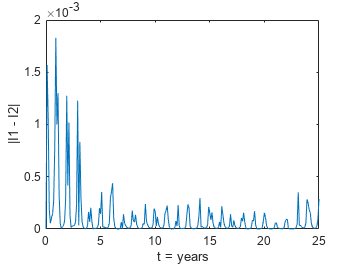

  %plot difference for I  
     
     figure
     plot(t1,abs(I1-I2))
     ylabel("|I1 - I2|")
     xlabel("t = years")

     norm(I1-I2)

ans = 0.0042

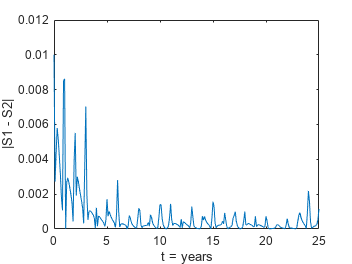

  %plot difference for S  
     figure
     plot(t1,abs(S1-S2))
     ylabel("|S1 - S2|")
     xlabel("t = years")

     
     norm(S1-S2)

ans = 0.0248

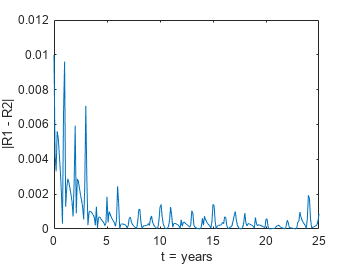

     %plot difference for R  
     figure
     plot(t1,abs(R1-R2))
      ylabel("|R1 - R2|")
     xlabel("t = years")

     norm(R1-R2)

ans = 0.0244

     function caller2() %caller function for chaotic 2d space

    x0 = [0.5; 0.02;0.48] ;
    tspan = [0 30]; 
    [t,x] = ode45(@example1, tspan, x0);

    figure
    plot(x(:,1),x(:,2),"Color",'blue','LineWidth',.1), hold on
    ylim([0 .15])
    xlim([0 1])
    ylabel("I")
    xlabel("S")
    title("Chaotic behavior at b =100 , b1 = .65")
end
function caller3() %caller function for periodic 2d space

    x0 = [0.5; 0.02;0.48] ;
    tspan = [0 30]; 
    [t,x] = ode45(@example2, tspan, x0);

    figure
    plot(x(:,1),x(:,2),"Color",'blue','LineWidth',.1), hold on
    ylim([0 .15])
    xlim([0 1])
    ylabel("I")
    xlabel("S")
    title("Chaotic behavior at b =100 , b1 = .1")
    



 

end

%function that constucts time series for when the system is not chaotic at
%b=.1
function xprime = example1(t,x)

    m    = .015;
    b   = 100;
    g    = 50;
    w    = 1;
    b1 = .1;
    L = b*(1 + b1*cos(pi*2*t)); 
    xprime = [m - m*x(1) - L*x(1)*x(2) + w*x(3); 
               L*x(1)*x(2) - m*x(2) - g*x(2); 
              g*x(2) - m*x(3) - w*x(3)];              
end

%function that constucts time series for when the system is chaotic at
%b=.65
function xprime1 = example2(t,x)

    m    = .015;
    b   = 100;
    g    = 50;
    w    = 1;
    b1 = .65;
    L = b*(1 + b1*cos(pi*2*t)); 
    xprime1 = [m - m*x(1) - L*x(1)*x(2) + w*x(3); 
               L*x(1)*x(2) - m*x(2) - g*x(2); 
              g*x(2) - m*x(3) - w*x(3)];   
  
end







function xprime2 = example4(t,x)

    m    = .015;
    b   = 100;
    g    = 50;
    w    = 1;
    b1 = .0;
    L = b*(1 + b1*cos(pi*2*t)); 
    xprime2 = [m - m*x(1) - L*x(1)*x(2) + w*x(3); 
               L*x(1)*x(2) - m*x(2) - g*x(2); 
              g*x(2) - m*x(3) - w*x(3)];              
end
function caller7() 

    x0    = [.99 .01 0]; 
    tspan = [0 100]; 
    [t,x] = ode45(@example12, tspan, x0);

    figure 
    plot(t,x(:,2),"Color",'red','LineWidth',1.5), hold on
  
    
    ylim([0 .0001])
    xlim([0 100])
    xlabel("t = years")
    ylabel("Percentage of Population")
    legend("I")
    title("Endemic equlibrium ,b =50.1, IC =(.99, .01 , 0)")
 

end

% The derivative 
function xprime12 = example12(t,x)

    m    = .015;
    b   = 50.1;
    g    = 50;
    w    = 1;
    xprime12 = [m - m*x(1) - b*x(1)*x(2) + w*x(3); 
               b*x(1)*x(2) - m*x(2) - g*x(2); 
              g*x(2) - m*x(3)-w*x(3)];              
end
